% ========================================================================
% Purpose:
%   Lodd data from numerical simulations of the time-delayed Furuta pendulum (xData) and a prior tangent-space guess,
%   fit an SSM-based ROM in a delay embedding space from scalar observable time series,
%   validate on a test set, visualize, and save IMInfo/RDInfo.
%
% Inputs:
%   SSMDim, overEmbed, sliceInt, SSMOrder, ROMOrder, lag
%
% Outputs:
%   Saves: RDInfoNormalForm.mat, IMInfo.mat in `folder`
% ========================================================================

clearvars; close all; clc
variousDir = fullfile(pwd,'..','..','..','Various');
assert(isfolder(variousDir),'Missing Various folder.');

run(fullfile(variousDir,'install.m'));

SSMLearn: Data-driven Reduced Order Models for Nonlinear Dynamical Systems
License: GNUv3.0


SSMLearn successfully installed!
 
Checking SSMTool is installed...


% ----- Config -----
SSMDim     = 4;
overEmbed  = 125;
sliceInt   = [0, 70];   
SSMOrder   = 1;
ROMOrder   = 6;
lag        = 10;       

folderForTangentSpaceGuess = 'Ts29ms_FurutaTimeDelay';


folder    = 'Ts31ms_FurutaTimeDelay';

% ----- Load IMInfo (to get initial tangent space guess) -----
iminfoPath = fullfile(folderForTangentSpaceGuess, 'IMInfo.mat');
if exist(iminfoPath, 'file')
    load(iminfoPath, 'IMInfo');
    fprintf('Loaded file: %s\n', iminfoPath);
else
    error('IMInfo.mat not found in %s', folderForTangentSpaceGuess);
end

Loaded file: Ts29ms_FurutaTimeDelay/IMInfo.mat


V_guess = IMInfo.parametrization.tangentSpaceAtOrigin;

% ----- Load xData -----
xdataPath = fullfile(folder, 'xDataKp_15.5_Kd_5.45.mat');
if exist(xdataPath, 'file')
    load(xdataPath, 'xData');
    fprintf('Loaded file: %s\n', xdataPath);
else
    error('xData file not found: %s', xdataPath);
end

Loaded file: Ts31ms_FurutaTimeDelay/xDataKp_15.5_Kd_5.45.mat


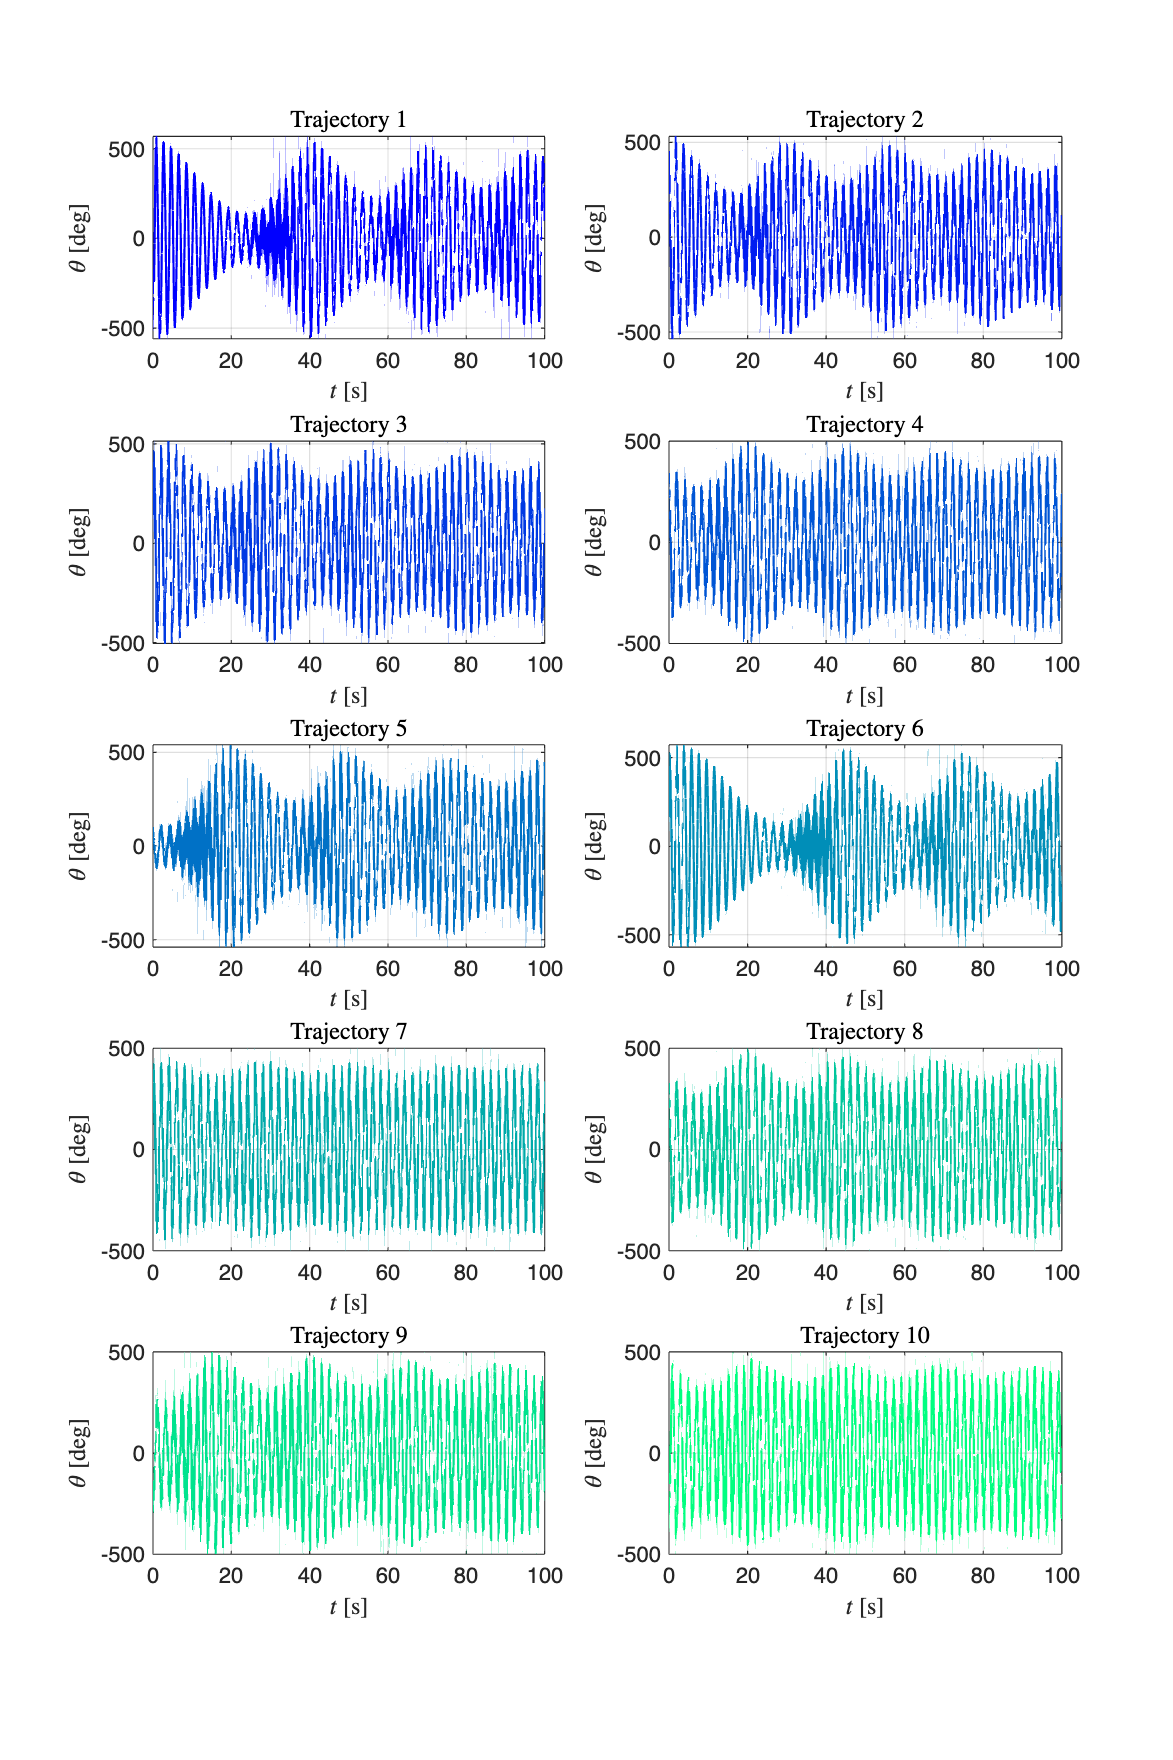


nTraj = size(xData, 1);

% ----- Train/Test split -----
indTest  = [5];                   
indTrain = setdiff(1:nTraj, indTest);   

% ----- Quick visualization of theta observable -----
nCols = 2;
nRows = ceil(nTraj / nCols);
colors = winter(nTraj);

figure('Color', 'w', 'Position', [300, 300, 1000, 1500]);
for i = 1:nTraj
    subplot(nRows, nCols, i); hold on; grid on; box on;
    t  = xData{i,1};
    Y  = xData{i,2};
    th = Y(1,:);                 % theta row
    plot(t, rad2deg(th), 'LineWidth', 1, 'Color', colors(i,:));
    xlabel('$t$ [s]', 'Interpreter', 'latex');
    ylabel('$\theta$ [deg]', 'Interpreter', 'latex');
    title(sprintf('Trajectory %d', i), 'Interpreter','latex');
end


xData1 = [];
for i = 1:nTraj
    xData1{i,1} = xData{i,1};
    xData1{i,2} = xData{i,2}(1,:);
end
% ----- Build delay-embedded coordinates -----
[yData, opts_embd] = coordinatesEmbedding(xData1, SSMDim, ...
    'OverEmbedding', overEmbed, 'TimeStepping', lag); 

The 134 embedding coordinates consist of the measured state and its 133 time-delayed measurements.


Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1        0.0438399                         0.436
     1           3        0.0123601       0.292954         0.0519  
     2           4        0.0119173              1          0.158  
     3           6         0.011404       0.245144         0.0368  
     4           8        0.0112102       0.467443         0.0403  
     5          10        0.0108644       0.515634         0.0378  
     6          11        0.0105789              1         0.0536  
     7          12       0.00861226              1         0.0411  
     8          13       0.00570208              1          0.023  
     9          14       0.00539344              1         0.0452  
    10          16       0.00524957       0.175719         0.0224  
    11          17

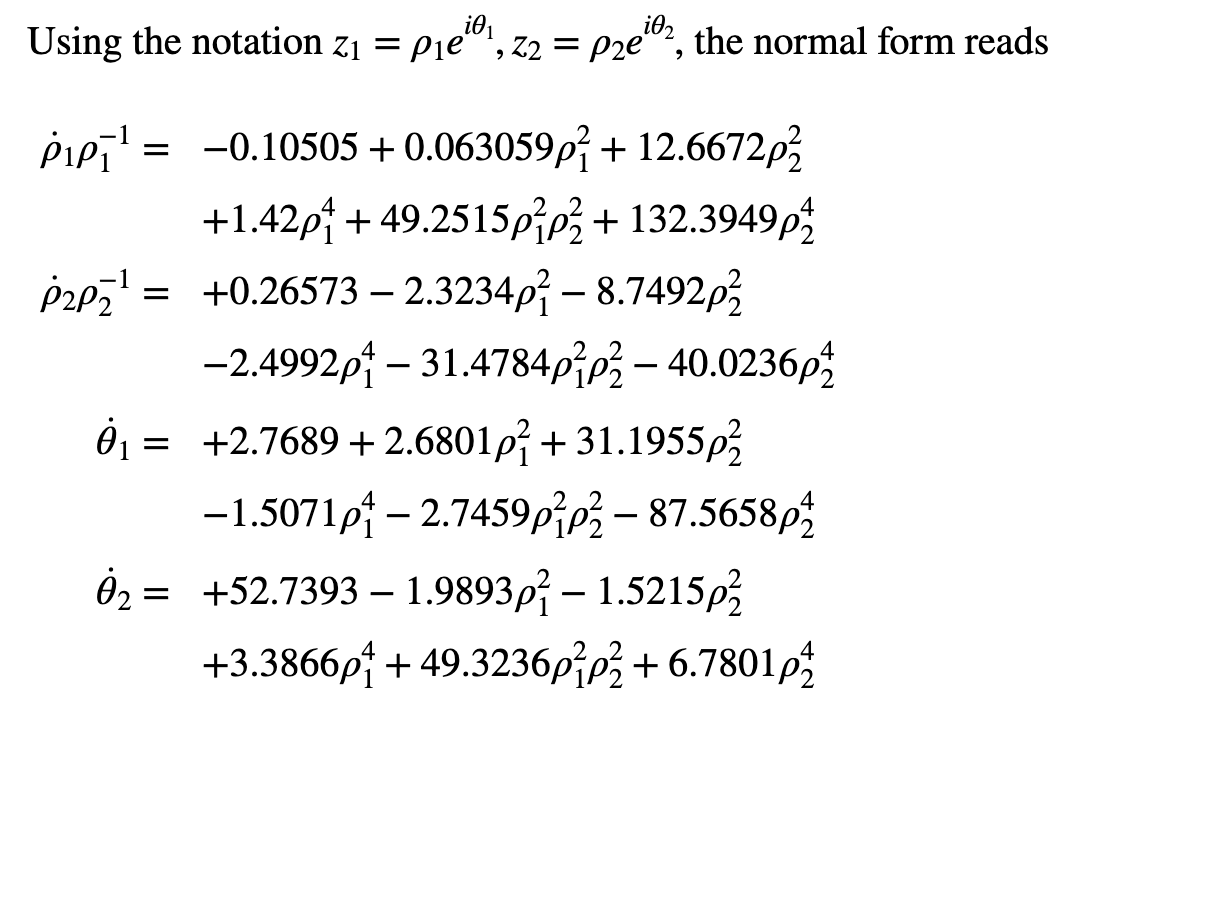

yDataTrunc = sliceTrajectories(yData, sliceInt);

% ----- Geometry (use prior tangent space as initial guess --> this prevent vector swapping or changing sign) -----
outdof = [1];    % 1: theta, 2: thetadot, 3: phidot (for plotting)
IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder, 'V_e0', V_guess);
etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

% ----- Fit reduced dynamics and advect -----
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform', 'MaxIter', 300);


[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc); 

% ----- Linear part eigenvalues -----
linearPart = RDInfo.reducedDynamics.coefficients(1:SSMDim, 1:SSMDim);
[~, Drd] = eig(linearPart); 
disp('Eigenvalues of linear part (reduced dynamics):');

Eigenvalues of linear part (reduced dynamics):


disp(diag(Drd).');

  -0.1051 + 2.7689i  -0.1051 - 2.7689i   0.2657 +52.7393i   0.2657 -52.7393i



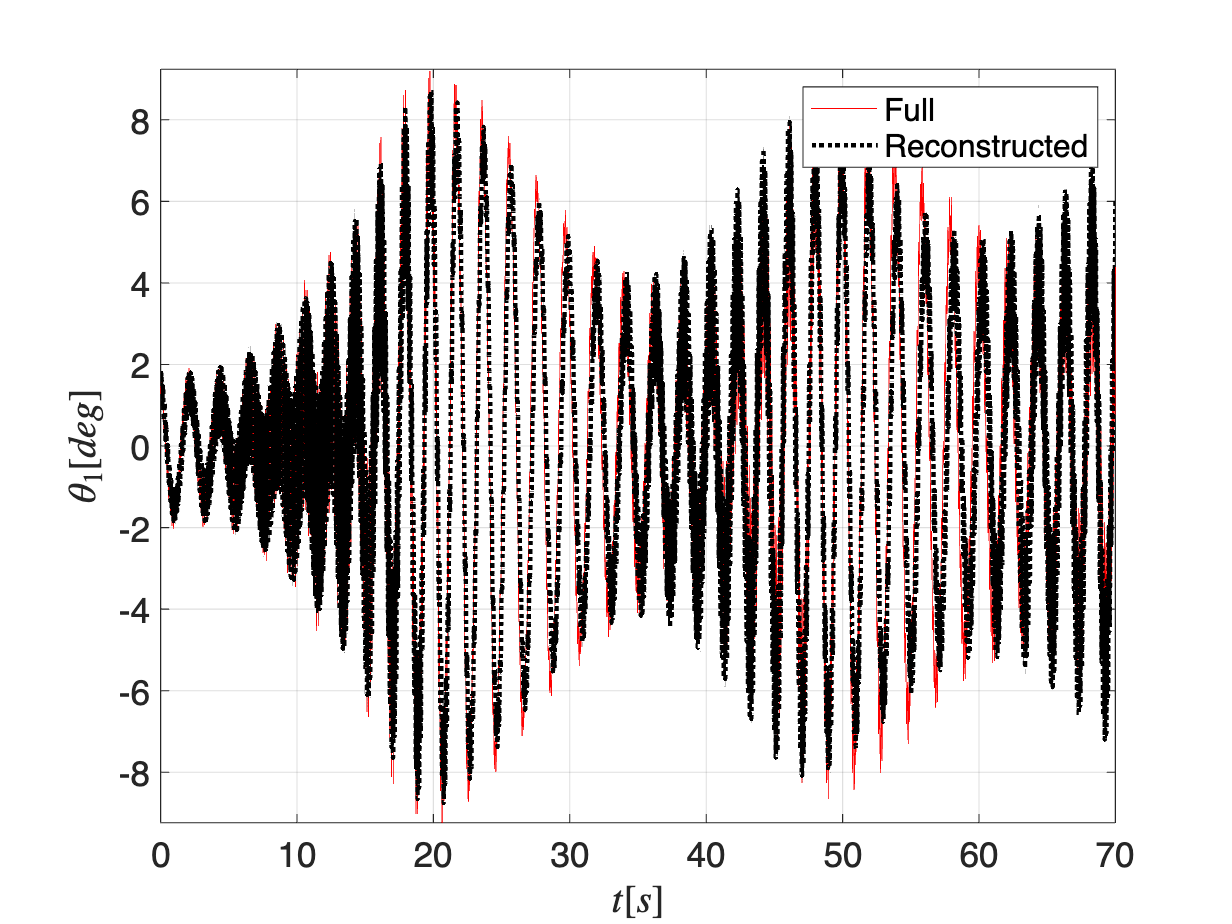


% ----- Compare SSM prediction vs Numerical simulation (test set) -----
plotTrajectoriesFuruta(yDataTrunc(indTest,:), yRec(indTest,:), 'm', outdof, 'Color', 'red');
xlim(sliceInt);


% ----- Save outputs -----
if ~exist(folder, 'dir')
    mkdir(folder);
    fprintf('Created folder: %s\n', folder);
end
RDInfo_filepath = fullfile(folder, 'RDInfo.mat');
IMInfo_filepath = fullfile(folder, 'IMInfo.mat');

if exist('RDInfo', 'var'), save(RDInfo_filepath, 'RDInfo'); fprintf('Saved: %s\n', RDInfo_filepath); else, fprintf('RDInfo not found. Not saved.\n'); end

Saved: Ts31ms_FurutaTimeDelay/RDInfo.mat


if exist('IMInfo', 'var'), save(IMInfo_filepath, 'IMInfo'); fprintf('Saved: %s\n', IMInfo_filepath); else, fprintf('IMInfo not found. Not saved.\n'); end

Saved: Ts31ms_FurutaTimeDelay/IMInfo.mat


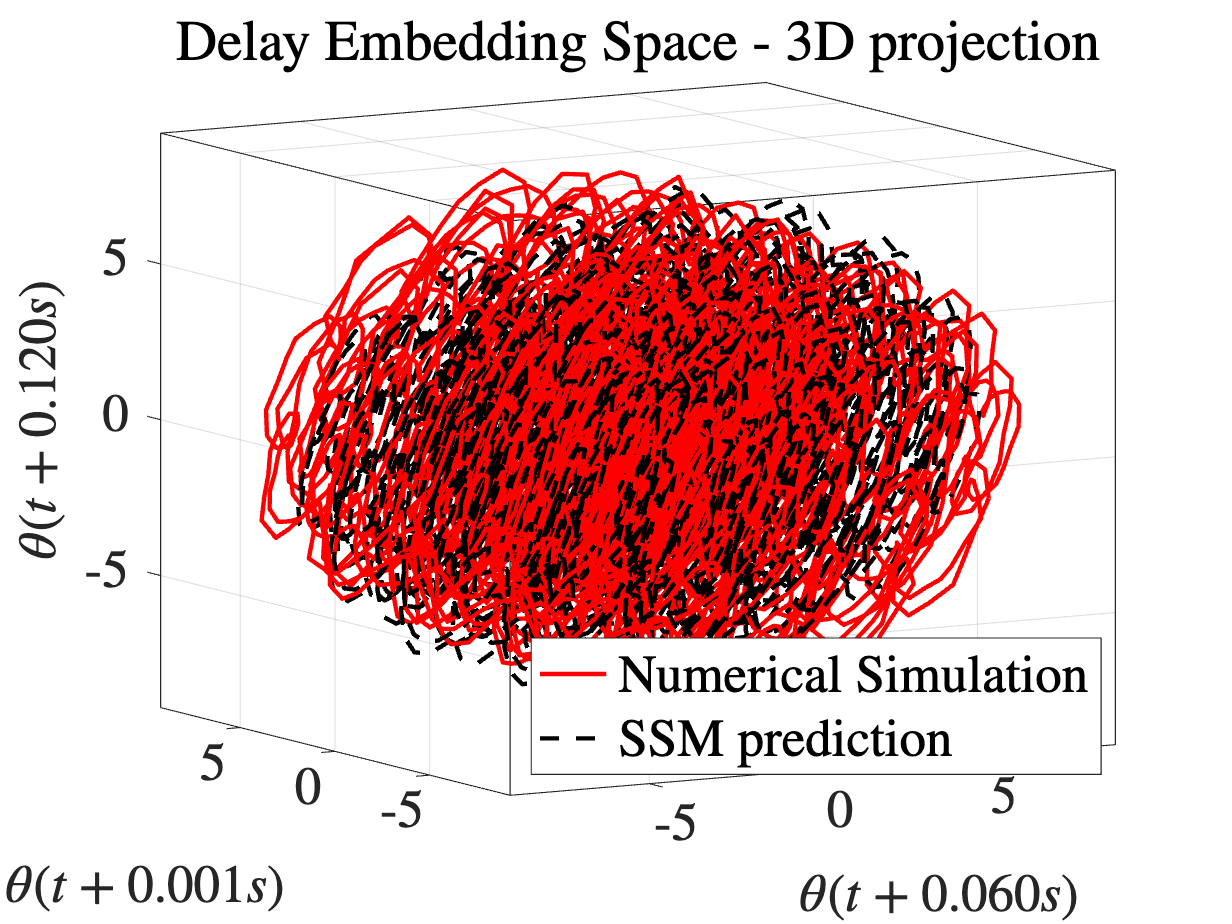


% ----- 3D delay-embedding projection -----
ind = indTest(1);
d1 = 1; d2 = 60; d3 = 120;           % delay coordinates to plot
dt = xData{1,1}(2) - xData{1,1}(1);   % sampling time

lfnt = 24; tfnt = 24; lw = 2;

figure('Color','w'); hold on; grid on; axis tight;
plot3(yDataTrunc{ind,2}(d1,:), yDataTrunc{ind,2}(d2,:), yDataTrunc{ind,2}(d3,:), ...
      'r-', 'LineWidth', lw);
plot3(yRec{ind,2}(d1,:),     yRec{ind,2}(d2,:),     yRec{ind,2}(d3,:), ...
      'k--', 'LineWidth', lw);

set(gca, 'FontSize', tfnt, 'FontName','Helvetica', 'TickLabelInterpreter','latex', 'Box','on', 'Color','white');

xlabel( sprintf('$\\theta(t+%.3fs)$', d1*dt), 'Interpreter','latex', 'FontSize', lfnt );
ylabel( sprintf('$\\theta(t+%.3fs)$', d2*dt), 'Interpreter','latex', 'FontSize', lfnt );
zlabel( sprintf('$\\theta(t+%.3fs)$', d3*dt), 'Interpreter','latex', 'FontSize', lfnt );

title('Delay Embedding Space - 3D projection', 'Interpreter','latex','FontSize', lfnt+2);
legend({'Numerical Simulation','SSM prediction'}, 'Interpreter','latex','FontSize', tfnt, 'Location','best');
view([120 -10]);